## Task 1

fprintf("*----------------------Task1---------------------*")

*----------------------Task1---------------------*

%1.a. 
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = [1500, 1600, 1700, 1800, 1900];  % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)
b = 10^-6;                                % Bit Error Rate

N = 20;                                   % number of simulation

pkt_delay = zeros(1, length(lambda));
error_delay = zeros(1, length(lambda));
pkt_loss = zeros(1,length(lambda));
error_loss = zeros(1,length(lambda));

for i = 1:length(lambda)

    PL = zeros(1, N);
    APD = zeros(1, N);
    MPD = zeros(1, N);
    TT = zeros(1, N);
    
    for j = 1:N
        [PL(j), APD(j), MPD(j), TT(j)] = Simulator2(lambda(i), C, f, P, b);
    end

    alfa = 0.1; % 90% confidence interval

    AVERAGE = mean(PL);
    TERM = norminv(1-alfa/2)*sqrt(var(PL)/N);
    fprintf("Packet Loss (%%)       = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss(i) = AVERAGE;
    error_loss(i) = TERM;

    AVERAGE = mean(APD);
    TERM = norminv(1-alfa/2)*sqrt(var(APD)/N);
    fprintf("Av. Packet Delay (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay(i) = AVERAGE;
    error_delay(i) = TERM;

end

Packet Loss (%)       = 4.91e-01 +- 7.27e-03


Av. Packet Delay (ms)  = 1.85e+00 +- 1.19e-02


Packet Loss (%)       = 4.89e-01 +- 6.60e-03


Av. Packet Delay (ms)  = 2.29e+00 +- 2.27e-02


Packet Loss (%)       = 4.88e-01 +- 1.03e-02


Av. Packet Delay (ms)  = 3.01e+00 +- 3.59e-02


Packet Loss (%)       = 4.97e-01 +- 8.36e-03


Av. Packet Delay (ms)  = 4.36e+00 +- 8.13e-02


Packet Loss (%)       = 4.92e-01 +- 7.92e-03


Av. Packet Delay (ms)  = 8.43e+00 +- 3.06e-01


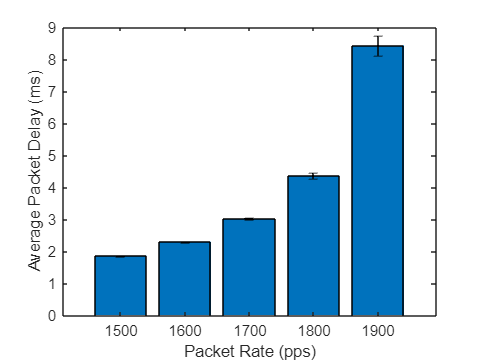


figure(1)
bar(categorical(lambda), pkt_delay)
xlabel("Packet Rate (pps)")
ylabel("Average Packet Delay (ms)")
hold on
er = errorbar(categorical(lambda), pkt_delay, error_delay, error_delay);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

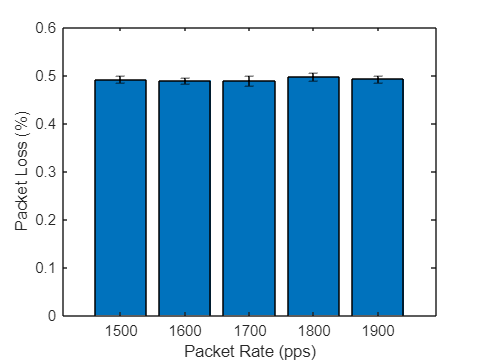


%%% Plot the results
figure(2)
bar(categorical(lambda), pkt_loss)
xlabel("Packet Rate (pps)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(lambda), pkt_loss, error_loss, error_loss);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

fprintf("-------------------------------------------")

-------------------------------------------

%%% conclusão: nota-se que a capacidade do link e tamanho de queue fixas, 
% o atraso médio dos pacotes aumente à medida que a taxa de chegada dos
% mesmos aumenta(i.e, a medida que packet rate aumenta).

%1.b. 
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = [1500, 1600, 1700, 1800, 1900];  % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)
b = 10^-4;                                % Bit Error Rate

N = 20;                                   % number of simulation

pkt_delay = zeros(1, length(lambda));
error_delay = zeros(1, length(lambda));
pkt_loss = zeros(1,length(lambda));
error_loss = zeros(1,length(lambda));

for i = 1:length(lambda)

    PL = zeros(1, N);
    APD = zeros(1, N);
    MPD = zeros(1, N);
    TT = zeros(1, N);
    
    for j = 1:N
        [PL(j), APD(j), MPD(j), TT(j)] = Simulator2(lambda(i), C, f, P, b);
    end

    alfa = 0.1; % 90% confidence interval

    AVERAGE = mean(PL);
    TERM = norminv(1-alfa/2)*sqrt(var(PL)/N);
    fprintf("Packet Loss (%%)       = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss(i) = AVERAGE;
    error_loss(i) = TERM;

    AVERAGE = mean(APD);
    TERM = norminv(1-alfa/2)*sqrt(var(APD)/N);
    fprintf("Av. Packet Delay (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay(i) = AVERAGE;
    error_delay(i) = TERM;

end

Packet Loss (%)       = 3.28e+01 +- 4.17e-02


Av. Packet Delay (ms)  = 1.67e+00 +- 1.16e-02


Packet Loss (%)       = 3.28e+01 +- 4.20e-02


Av. Packet Delay (ms)  = 2.09e+00 +- 2.09e-02


Packet Loss (%)       = 3.28e+01 +- 4.56e-02


Av. Packet Delay (ms)  = 2.83e+00 +- 2.66e-02


Packet Loss (%)       = 3.29e+01 +- 3.83e-02


Av. Packet Delay (ms)  = 4.24e+00 +- 5.79e-02


Packet Loss (%)       = 3.28e+01 +- 5.02e-02


Av. Packet Delay (ms)  = 7.86e+00 +- 1.91e-01


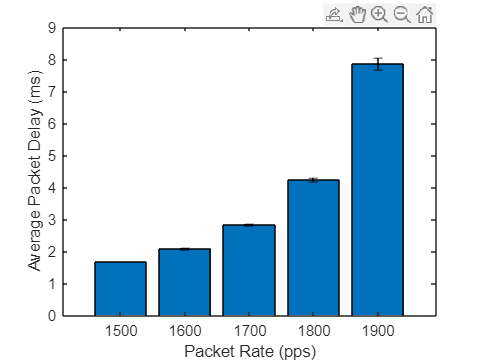


figure(1)
bar(categorical(lambda), pkt_delay)
xlabel("Packet Rate (pps)")
ylabel("Average Packet Delay (ms)")
hold on
er = errorbar(categorical(lambda), pkt_delay, error_delay, error_delay);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

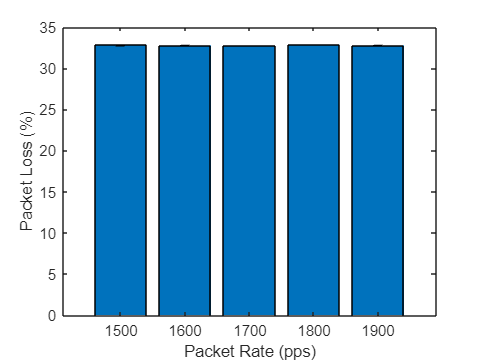


%%% Plot the results
figure(2)
bar(categorical(lambda), pkt_loss)
xlabel("Packet Rate (pps)")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(lambda), pkt_loss, error_loss, error_loss);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

fprintf("-------------------------------------------")

-------------------------------------------

%% conclusão: Verifica-se que, quanto menor é BER, menor é a perda de pacotes comparando com
% alinea 1.a.

%1.c. [using 1.a.]

P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = [1500, 1600, 1700, 1800, 1900];  % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)

%Calculation of the probability associated to each packet size  
ne = (109 - 65 + 1) + (1517 - 111 + 1);   % number of elements or packets - size of the packets in bytes
p1 = 100 - (19 + 23 + 17);                % probability of remaining packets or elements
p2 = p1/ne ;                              % probability of each packet

pkt_size = 64:1518;                       % in bytes

b1 = 10^-6;                                % Bit Error Rate
b2 = 10^-4;                                % Bit Error Rate

for j = 1:length(C)
    S = (pkt_size .* 8)./(C(j)*10^6);
    S2 = (pkt_size .* 8)./(C(j)*10^6);
    for i = 1:length(pkt_size)
        if i == 1
            S(i) = S(i)*0.19;
            S2(i) = S2(i)^2*0.19;
        elseif i == 110-64+1
            S(i) = S(i)*0.23;
            S2(i) = S2(i)^2*0.23;
        elseif i == 1518-64+1
            S(i) = S(i)*0.17;
            S2(i) = S2(i)^2*0.17;
        else
            S(i) = S(i)*(p2/100);
            S2(i) = S2(i)^2*(p2/100);
        end
    end
    
    ES = sum(S);
    ES2 = sum(S2);
    
     avg_pkt_loss_b1 = ES + 1-(1- b1).^(pkt_size.*8);
     avg_pkt_loss_b2 = ES + 1-(1- b2).^(pkt_size.*8);
    fprintf("Average Packet Loss(10^-6):  %.2e ms\n",  avg_pkt_loss_b1);
    fprintf("Average Packet Loss(10^-4):  %.2e ms\n",  avg_pkt_loss_b2);
end

Average Packet Loss(10^-6):  1.01e-03 ms
Average Packet Loss(10^-6):  1.02e-03 ms
Average Packet Loss(10^-6):  1.02e-03 ms
Average Packet Loss(10^-6):  1.03e-03 ms
Average Packet Loss(10^-6):  1.04e-03 ms
Average Packet Loss(10^-6):  1.05e-03 ms
Average Packet Loss(10^-6):  1.06e-03 ms
Average Packet Loss(10^-6):  1.06e-03 ms
Average Packet Loss(10^-6):  1.07e-03 ms
Average Packet Loss(10^-6):  1.08e-03 ms
Average Packet Loss(10^-6):  1.09e-03 ms
Average Packet Loss(10^-6):  1.10e-03 ms
Average Packet Loss(10^-6):  1.10e-03 ms
Average Packet Loss(10^-6):  1.11e-03 ms
Average Packet Loss(10^-6):  1.12e-03 ms
Average Packet Loss(10^-6):  1.13e-03 ms
Average Packet Loss(10^-6):  1.14e-03 ms
Average Packet Loss(10^-6):  1.14e-03 ms
Average Packet Loss(10^-6):  1.15e-03 ms
Average Packet Loss(10^-6):  1.16e-03 ms
Average Packet Loss(10^-6):  1.17e-03 ms
Average Packet Loss(10^-6):  1.18e-03 ms
Average Packet Loss(10^-6):  1.18e-03 ms
Average Packet Loss(10^-6):  1.19e-03 ms
Average Packet L

Average Packet Loss(10^-4):  5.04e-02 ms
Average Packet Loss(10^-4):  5.12e-02 ms
Average Packet Loss(10^-4):  5.19e-02 ms
Average Packet Loss(10^-4):  5.27e-02 ms
Average Packet Loss(10^-4):  5.34e-02 ms
Average Packet Loss(10^-4):  5.42e-02 ms
Average Packet Loss(10^-4):  5.50e-02 ms
Average Packet Loss(10^-4):  5.57e-02 ms
Average Packet Loss(10^-4):  5.65e-02 ms
Average Packet Loss(10^-4):  5.72e-02 ms
Average Packet Loss(10^-4):  5.80e-02 ms
Average Packet Loss(10^-4):  5.87e-02 ms
Average Packet Loss(10^-4):  5.95e-02 ms
Average Packet Loss(10^-4):  6.02e-02 ms
Average Packet Loss(10^-4):  6.10e-02 ms
Average Packet Loss(10^-4):  6.17e-02 ms
Average Packet Loss(10^-4):  6.25e-02 ms
Average Packet Loss(10^-4):  6.32e-02 ms
Average Packet Loss(10^-4):  6.40e-02 ms
Average Packet Loss(10^-4):  6.47e-02 ms
Average Packet Loss(10^-4):  6.55e-02 ms
Average Packet Loss(10^-4):  6.62e-02 ms
Average Packet Loss(10^-4):  6.70e-02 ms
Average Packet Loss(10^-4):  6.77e-02 ms
Average Packet L

fprintf("-------------------------------------------")

## Task 2

% 2.a.
P = 100000;                               % Stopping criterion
C = 10;                                   % Link capacity in Mbps
lambda = 1500;                            % Values for packet rate in pps
f = 1000000;                              % Queue size(in bytes)
b = 10^-5;                                % Bit Error Rate

N = 20;                                   % number of simulation
n = [10, 20, 30, 40];                     % number of adidional VoIP packets flows

pkt_delay_voip = zeros(1, length(lambda));
error_delay_voip = zeros(1, length(lambda));
pkt_loss_voip = zeros(1, length(lambda)); 
error_loss_voip = zeros(1, length(lambda)); 

pkt_delay_data = zeros(1, length(lambda));
error_delay_data = zeros(1, length(lambda));
pkt_loss_data = zeros(1, length(lambda));  
error_loss_data = zeros(1, length(lambda));  

AVERAGE = zeros(4,4);
TERM = zeros(4,4);

for j = 1:length(n)
    PLd = zeros(1, N);
    PLv = zeros(1, N);
    APDd = zeros(1, N);
    APDv = zeros(1, N);
    MPDd = zeros(1, N);
    MPDv = zeros(1, N);
    TT = zeros(1, N);
    
    for i = 1:N
        [PLd(i), PLv(i), APDd(i), APDv(i), MPDd(i), MPDv(i), TT(i)] = Simulator3A(lambda,C,f,P,n(j), b);
    end    
    alfa = 0.1; % 90% confidence interval 
    
    
    AVERAGE = mean(PLd);
    TERM = norminv(1-alfa/2)*sqrt(var(PLd)/N);
    fprintf("Packet Loss (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_data(j) = AVERAGE;
    error_loss_data(j) = TERM;

    AVERAGE = mean(APDd);
    TERM = norminv(1-alfa/2)*sqrt(var(APDd)/N);
    fprintf("Av. Packet Delay Data (ms)  = %.2e +- %.2e\n\n\n", AVERAGE, TERM);
    pkt_delay_data(j) = AVERAGE;
    error_delay_data(j) = TERM;

    AVERAGE = mean(PLv);
    TERM = norminv(1-alfa/2)*sqrt(var(PLv)/N);
    fprintf("Packet Loss VoIP (%%)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_loss_voip(j) = AVERAGE;
    error_loss_voip(j) = TERM;

    AVERAGE = mean(APDv);
    TERM = norminv(1-alfa/2)*sqrt(var(APDv)/N);
    fprintf("Av. Packet Delay VoIP (ms)  = %.2e +- %.2e\n", AVERAGE, TERM);
    pkt_delay_voip(j) = AVERAGE;
    error_delay_voip(j) = TERM;
 
end

Packet Loss (%)  = 4.76e+00 +- 3.12e-02


Av. Packet Delay Data (ms)  = 2.17e+00 +- 2.35e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 1.77e+00 +- 2.19e-02


Packet Loss (%)  = 4.73e+00 +- 2.91e-02


Av. Packet Delay Data (ms)  = 2.68e+00 +- 3.42e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 2.27e+00 +- 3.12e-02


Packet Loss (%)  = 4.69e+00 +- 4.39e-02


Av. Packet Delay Data (ms)  = 3.58e+00 +- 7.15e-02




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 3.18e+00 +- 6.75e-02


Packet Loss (%)  = 4.71e+00 +- 3.79e-02


Av. Packet Delay Data (ms)  = 5.74e+00 +- 2.04e-01




Packet Loss VoIP (%)  = 0.00e+00 +- 0.00e+00


Av. Packet Delay VoIP (ms)  = 5.33e+00 +- 1.99e-01


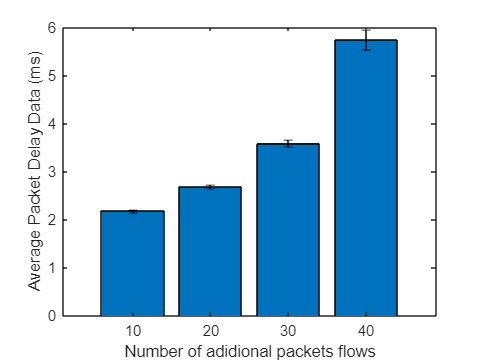



% Plot the results
figure(1)
bar(categorical(n), pkt_delay_data)
xlabel("Number of adidional packets flows")
ylabel("Average Packet Delay Data (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_data, error_delay_data, error_delay_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

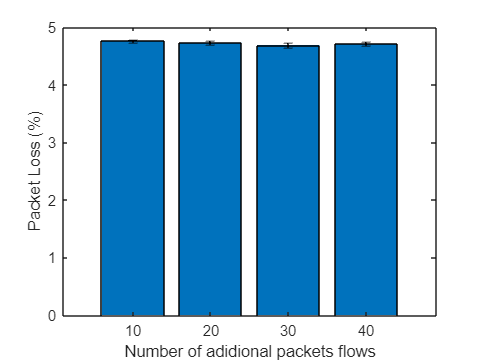


%%% Plot the results
figure(2)
bar(categorical(n), pkt_loss_data)
xlabel("Number of adidional packets flows")
ylabel("Packet Loss (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_data, error_loss_data, error_loss_data);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

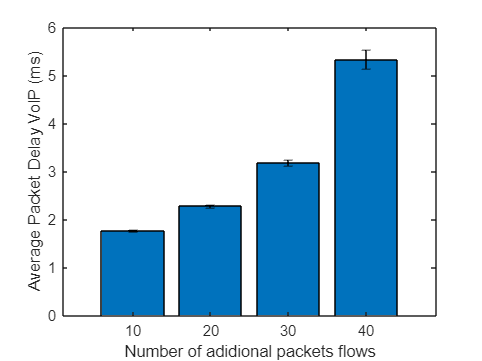


% Plot the results
figure(3)
bar(categorical(n), pkt_delay_voip)
xlabel("Number of adidional packets flows")
ylabel("Average Packet Delay VoIP (ms)")
hold on
er = errorbar(categorical(n), pkt_delay_voip, error_delay_voip, error_delay_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

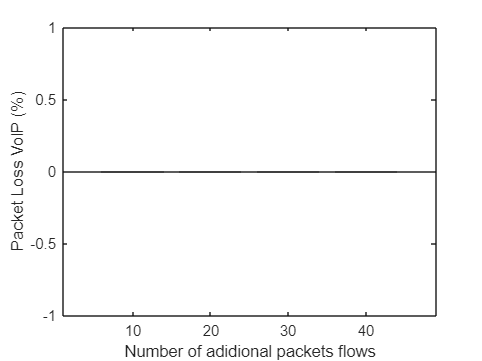


%%% Plot the results
figure(4)
bar(categorical(n), pkt_loss_voip)
xlabel("Number of adidional packets flows")
ylabel("Packet Loss VoIP (%)")
hold on
%%% Adding arror bars to the Plot
er = errorbar(categorical(n), pkt_loss_voip, error_loss_voip, error_loss_voip);
er.Color = [0 0 0];
er.LineStyle = 'none';
hold off;

fprintf("-------------------------------------------")

-------------------------------------------